# **Reaction essentiality across multiple models**

**Note: This tutorial is a draft and needs completion. Contributions welcome!**

**Authors: Miguel A.P. Oliveira, Diana C. El Assal-Jordan, Sylvain Arreckx and Ronan M.T. Fleming, Luxembourg Centre for Systems Biomedicine**

**Reviewers: **

## Introduction

During this tutorial, you will identify and compare which reactions are essential for ATP production within a set of metabolic models. This tutorial is particularly useful when studying metabolic functional abilities across multiple metabolic models.

This driver allows us to perform single reactions to identify essential ones that are required for ATP generation. This means that these essential reactions would carry a zero flux when optimising the ATP consumption reaction (ATPM).

Version 5/12/2017

## EQUIPMENT SETUP

## **Initialize the COBRA Toolbox **and set the solver

Please ensure that The CobraToolbox has been properly installed, and initialized using the `initCobraToolbox` function.

initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configuring solver enviro

 Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

			Support 	   LP 	 MILP 	   QP 	 MIQP 	  NLP
	----------------------------------------------------------------------
	cplex_direct 	active        	    0 	    0 	    0 	    0 	    -
	dqqMinos     	active        	    0 	    - 	    - 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    -
	gurobi       	active        	    1 	    1 	    1 	    1 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    - 	    -
	matlab       	active        	    0 	    - 	    - 	    - 	    0
	mosek        	active        	    0 	    0 	    0 	    - 	    -
	pdco         	active        	    1 	    - 	    1 	    - 	    -
	quadMinos    	active        	    0 	    - 	    - 	    - 	    0
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    -
	qpng         	passive       	    - 	    - 	    1 

The present tutorial can run with [glpk package](https://opencobra.github.io/cobratoolbox/deprecated/docs/cobra/solvers/changeCobraSolver.html), which does not require additional installation and configuration. Although, for the analysis of large models it is recommended to use the [GUROBI](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md) package.

changeCobraSolver('gurobi6','all')


 > Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on macOS 10.12.
 > The solver compatibility is not tested with MATLAB R2016a.
 > Solver for LP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on macOS 10.12.
 > The solver compatibility is not tested with MATLAB R2016a.
 > Solver for MILP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on macOS 10.12.
 > The solver compatibility is not tested with MATLAB R2016a.
 > Solver for QP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The compatibility can only be evaluated on macOS 10.12.
 > The solver compatibility is not tested with MATLAB R2016a.
 > Solver for MIQP problems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


## Define model directory

In this tutorial, we use the cardiac model `modelCardioMito` [1] and study reaction essentiality across multiple versions this model based on the carbon sources used. This models was extracted from the latest version of the database of the human cellular metabolism, Recon 3D. For extra information about metabolites structures and reactions, and to download the latest COBRA model releases, visit the Virtual Metabolic Human database (VMH, [https://vmh.life](https://vmh.life)). 

Before proceeding with the simulations, locate the directory with the cardiac models: 

modelName = 'cardiac_mit_glcuptake_atpmax.mat';
modelsDir = getDistributedModelFolder(modelName);

## PROCEDURE 

## **1. Load the **`modelCardioMito `**model at set objective function:**

load([modelsDir filesep modelName])

Since we are studying reaction essentiality define the reaction `ATPS4m` as the objective function:

objFun = 'ATPS4m';

## **2. Generate multiple cardiac models that use different carbon sources**

**2.1. Close exchange reactions:**

modelalter = modelCardioMito;
exchanges = {'EX_12dgr_m(e)'
    'EX_arachd(e)'
    'EX_co2(e)'
    'EX_coa(e)'
    'EX_crvnc(e)'
    'EX_cys-L(e)'
    'EX_glc(e)'
    'EX_glu-L(e)'
    'EX_gly(e)'
    'EX_glyc(e)'
    'EX_glyc3p(e)'
    'EX_hdca(e)'
    'EX_lac-L(e)'
    'EX_ocdca(e)'
    'EX_ocdcea(e)'
    'EX_ocdcya(e)'
    'EX_ps_m(e)'
    'EX_urea(e)'};
for i = 1:length(exchanges)
    modelalter = changeRxnBounds(modelalter,exchanges{i},0,'l');
end

**2.2. Generate multiple models by allowing different carbon sources to be fed into each model**

Select one carbon source to be fed into the model at a time using 20 units.

allModels = {};
for i = 1:length(exchanges)
    model = modelalter;
    % Change bound of the corresponding exchange reaction using 20 units
    model = changeRxnBounds(model, exchanges{i}, -20, 'l');
    
    % New model name
    str = exchanges{i};
    match = {'-','(e)'};
    for j=1:size(match,2)
        str = strrep(str, match{j},{''});
    end
    newModelName = horzcat(str{1},'_model');
    
    % Combine models in a structure
    allModels.(newModelName) = model;
end


**2.3 Delete every reaction in each model to study their essentiatity across:**

Perform single reaction deletion (`singleRxnDeletion.m`) across all models by using the function `essentialRxn4MultipleModels.m` 

TIMING: aprox. 10 seconds per model (~3min)

%allModels = '/hdd/work/sbgCloud/programReconstruction/projects/brainMetabolism/results/modelGeneration/models/cutoff_50'

[ essentialRxn4Models, dataStruct] = essentialRxn4MultipleModels(allModels, objFun);

 
Analysing model: 
EX_12dgr_m_model
Single reaction deletion analysis in progress ...

**2.4. Study reaction essentiality across all models by conditional search:**

**Define an essentiality threshold:** reactions for which its deletion resulted in an 'ATPS4mi' flux below the threshold value will be considered essential for the model.

essentialityRange = [-100,100]; %negative values only represent absent reactions

In the following heatmaps, reactions with the lowest positive flux values (minimum in `essentialityRange`) are coloured in red and reactions that carry flux (close the the higher flux value in `essentialityRange`) are coloured in black. Intermediate flux values will be coloured in orange (less flux) and yellow (more flux).

**2.4.1. Identify reactions that are essential in at least one model:**

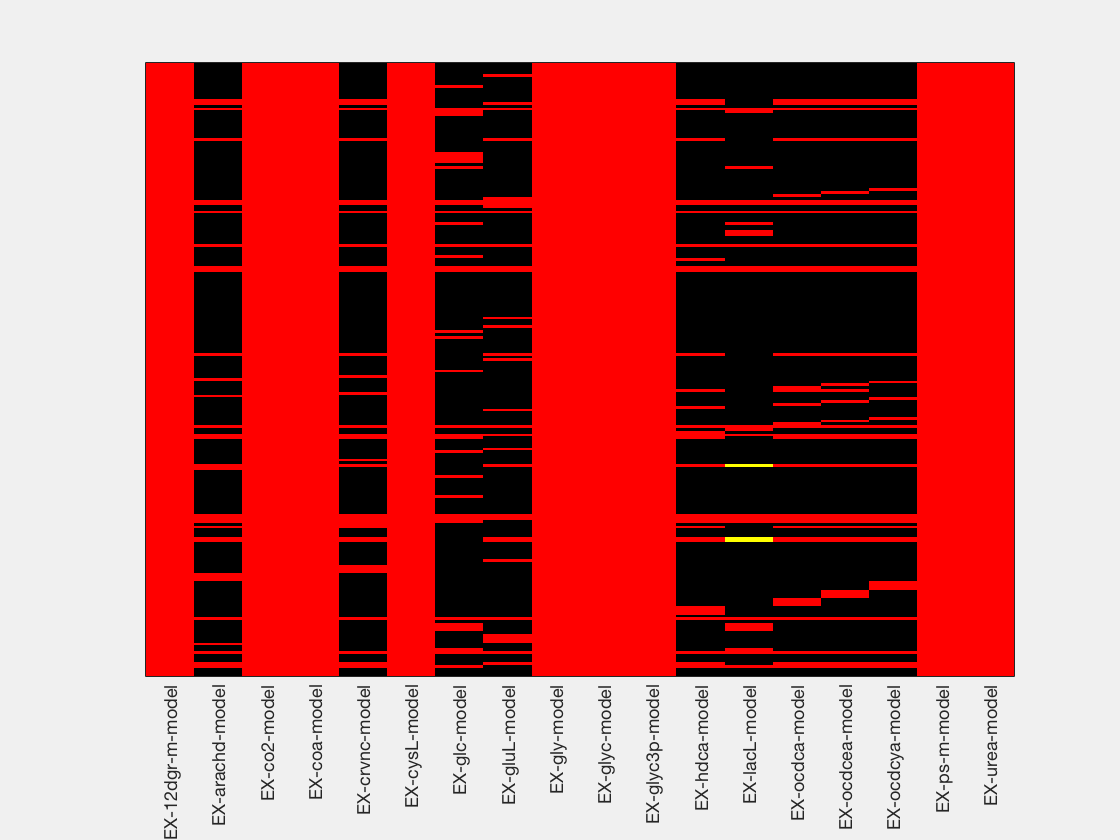

numModelsPresent = 1;
rxnsOfInterest_1Model = plotEssentialRxns( essentialRxn4Models, essentialityRange, numModelsPresent);

**2.4.2. Identify reactions that are essential in at least 11 models:**

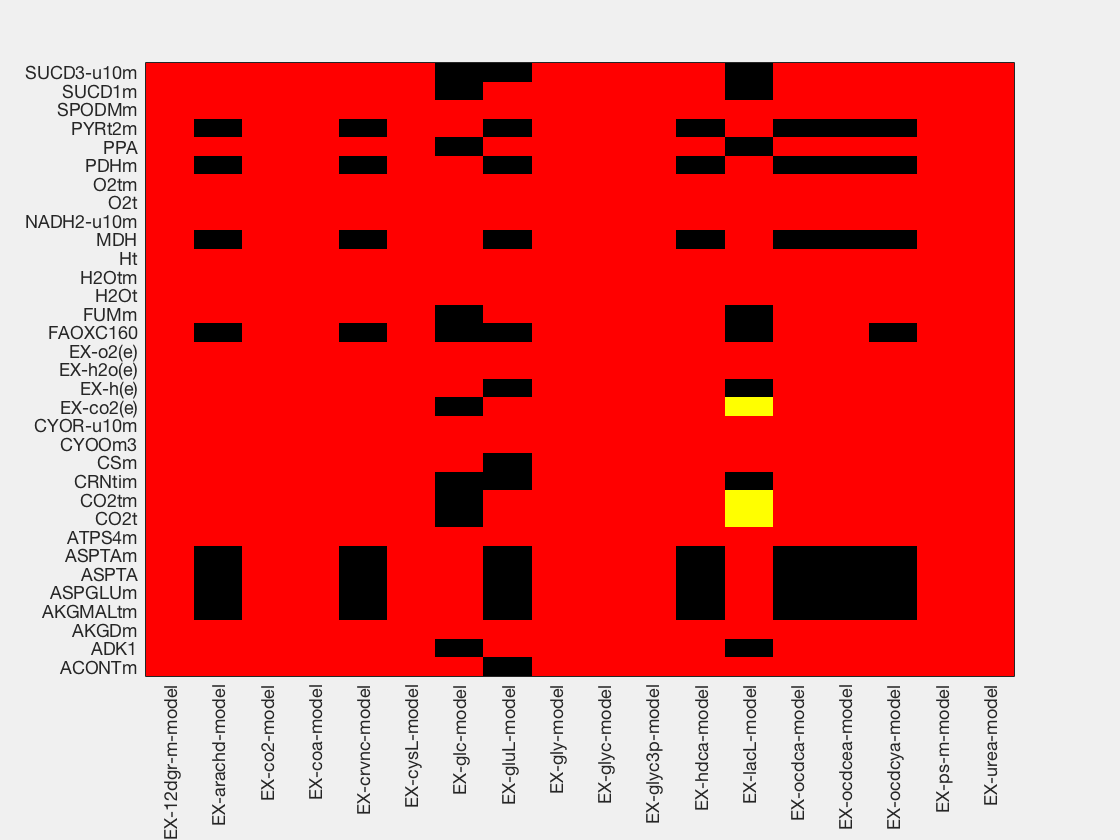

numModelsPresent = 11;
rxnsOfInterest_11Models = plotEssentialRxns( essentialRxn4Models, essentialityRange, numModelsPresent);

**2.4.3.  Identify reactions that are essential in at least 17 models:**

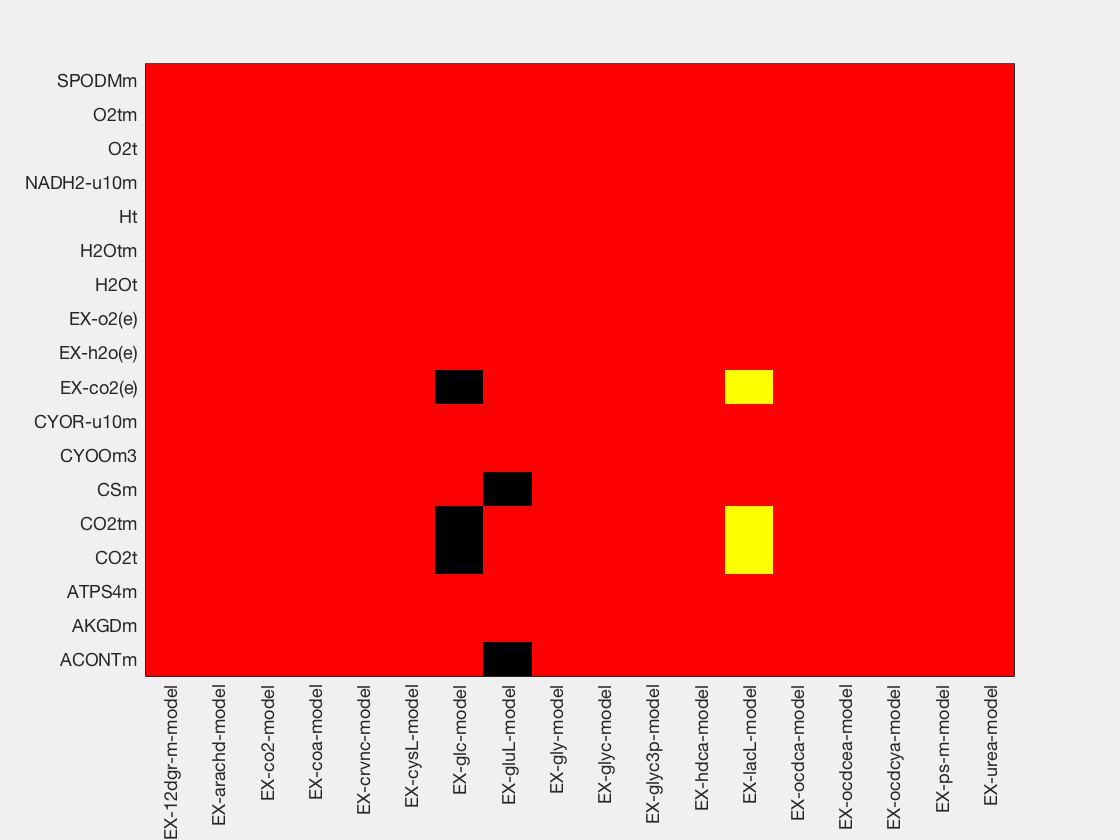

numModelsPresent = 17;
rxnsOfInterest_17Models = plotEssentialRxns( essentialRxn4Models, essentialityRange, numModelsPresent);

**2.4.4.  Identify reactions that are essential and present in all models:**

numModelsPresent = size(essentialRxn4Models(:,2:end),2);
rxnsOfInterest_allModels = plotEssentialRxns( essentialRxn4Models, essentialityRange, numModelsPresent);


 Attention: All non-essential reactions have flux above the threshold 


**2.4.5. Identify reactions that are essential and always present in all models:**

Allow only reactions that are present across all models by adjusting the lower value of the `essentialityRange` to a non-negative value.

essentialityRange = [0,0]; % only reactions

Now identify the present reactions that are essential in at least one model

numModelsPresent = 1;
presentRxnsOfInterest_1Model = plotEssentialRxns( essentialRxn4Models, essentialityRange, numModelsPresent);

**2.4.6. Identify reactions that are never essential in all models:**

Allow only reactions that are present across all models by adjusting the lower value of the `essentialityRange` to a positive value (e.g. 50 units).

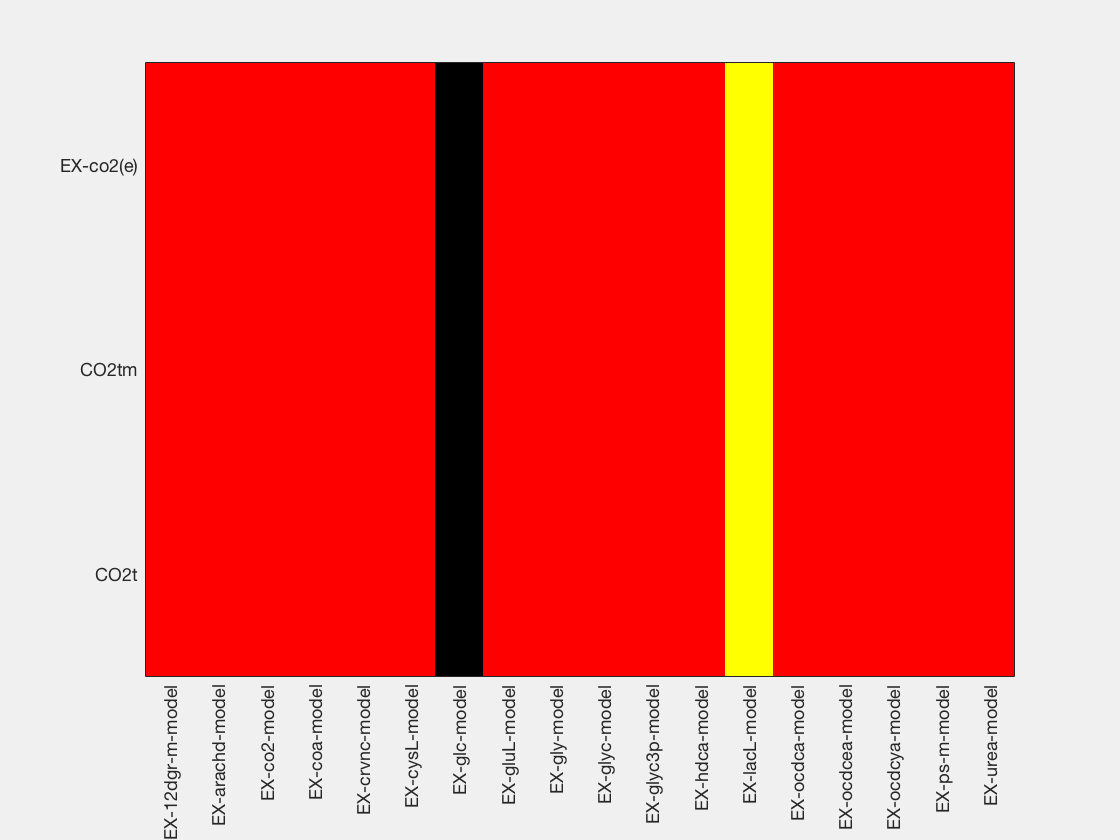

essentialityRange = [50,100]; % always positive fluxes
numModelsPresent = 1; 
rxnsOfInterest = plotEssentialRxns( essentialRxn4Models, essentialityRange, numModelsPresent);

## 3. Allow different max fluxes in NADH reaction and test reaction essentiality across all models

Use again the `modelCardioMito` model

titratioModel = modelCardioMito;

**3.1. Select the reaction **`NADH2-u10m`** to be titrated and the titration ranges**

reaction4titration = 'NADH2-u10m';
titrationFluxes = (-40:20:300);

Generate multiple models with bound constraint (`titrationFluxes`) in the reaction `NADH2-u10m`

allTitrationModels = {};
for i = 1:length(exchanges)
    model = titratioModel;
    % Change bound of the corresponding exchange reaction using 20 units
    model = changeRxnBounds(model, reaction4titration, titrationFluxes(i), 'b');
    
    % New model name
    str = reaction4titration;
    match = {'-','(e)'};
    for j=1:size(match,2)
        str = strrep(str, match{j},{''});
    end
    fluxValue = num2str(titrationFluxes(i));
    fluxValue = strrep(fluxValue, '-','minus');
    newModelName = horzcat(str{1,1},'Flux',fluxValue,'Model');

    % Combine models in a structure
    allTitrationModels.(newModelName) = model;
end

**3.2. Delete every reaction in each model to study their essentiatity across:**

[ essentialRxn4NADHModels, dataStruct] = essentialRxn4MultipleModels(allTitrationModels, objFun);

 
Analysing model: 
NADH2u10mFluxminus40Model
Single reaction deletion analysis in progress ...

**3.3. Study reaction essentiality across all models by conditional search:**

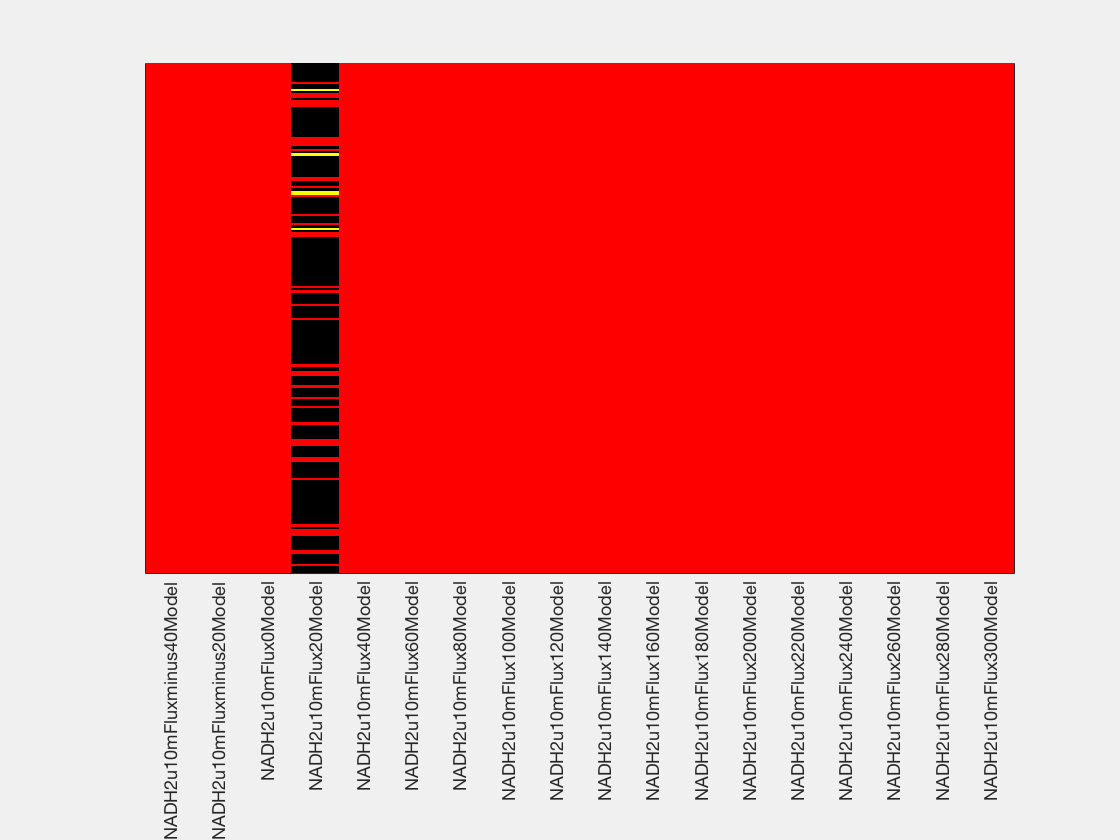

essentialityRange = [-100,100]; %negative values only represent absent reactions
numModelsPresent = 1; % essential reactions in at least 1 model
rxnsOfInterest_NADH1Model = plotEssentialRxns( essentialRxn4NADHModels, essentialityRange, numModelsPresent);